%Question 5
clc;
clear all;
close all;

N = 200;
a=-5;b=5;
sigmaSquared = 300;
%generating random points and gaussian noise
x = a + (b-a).*rand(N,1);
n = sqrt(sigmaSquared).*randn(N,1);

%generating datapoints
X = [x.^3 (x.^2) x];
weights = [5 -1 1]';
t = X*weights + n;

%training models

XSixth = zeros(N,6);
for i = 1:6
    XSixth(:,i) = x.^(i-1);
end
XLin = XSixth(:,1:2);
XCubic = XSixth(:,1:4);

%linear model
what_linear = ((XLin'*XLin)^(-1))*XLin'*t;

%cubic model
what_cubic = ((XCubic'*XCubic)^(-1))*XCubic'*t;

%sixth order model
what_sixth = ((XSixth'*XSixth)^(-1))*XSixth'*t;


%testing model
xtest = (-5:0.05:5)';
Xtest = zeros(length(xtest), 6);
for i = 1:6
    Xtest(:,i) = xtest.^(i-1);
end

XtestLinear = Xtest(:,1:2);
XtestCubic = Xtest(:, 1:4);

that_linear = XtestLinear*what_linear;
that_cubic = XtestCubic*what_cubic;
that_sixth = Xtest*what_sixth;

that_linear_var = zeros(length(that_linear),1);
that_cubic_var = zeros(length(that_cubic), 1);
that_sixth_var = zeros(length(that_sixth), 1);

for i = 1:length(xtest)
    ss = (1/N)*(t'*t - t'*XLin*what_linear);
    that_linear_var(i) = ss*XtestLinear(i,:)*((XLin'*XLin)^(-1))*XtestLinear(i,:)';
    ss = (1/N)*(t'*t - t'*XCubic*what_cubic);
    that_cubic_var(i) = ss*XtestCubic(i,:)*((XCubic'*XCubic)^(-1))*XtestCubic(i,:)';
    ss = (1/N)*(t'*t - t'*XSixth*what_sixth);
    that_sixth_var(i) = ss*Xtest(i,:)*((XSixth'*XSixth)^(-1))*Xtest(i,:)';
end


#### Plotting

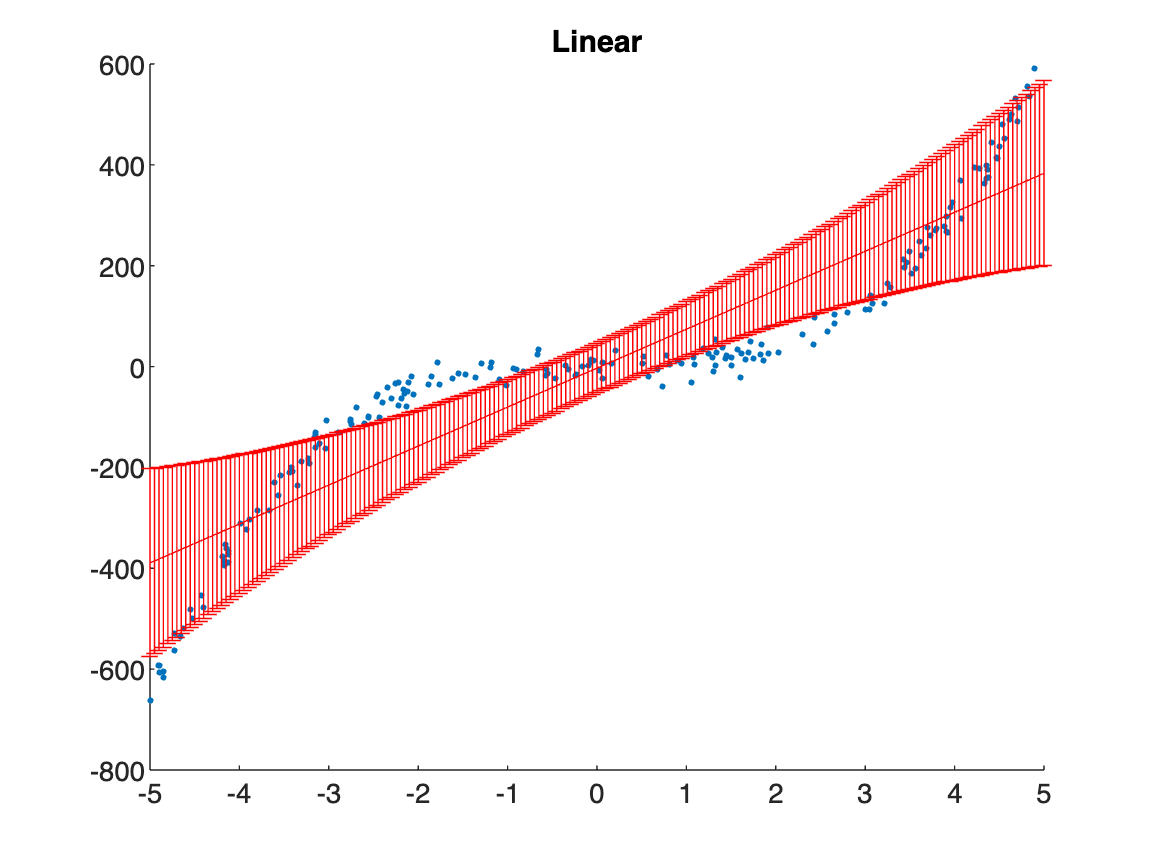

figure(1);
scatter(x,t,5,'filled')
hold on;
plot(xtest, that_linear, '-r');
errorbar(xtest, that_linear, that_linear_var, '-r')
title("Linear")
hold off;

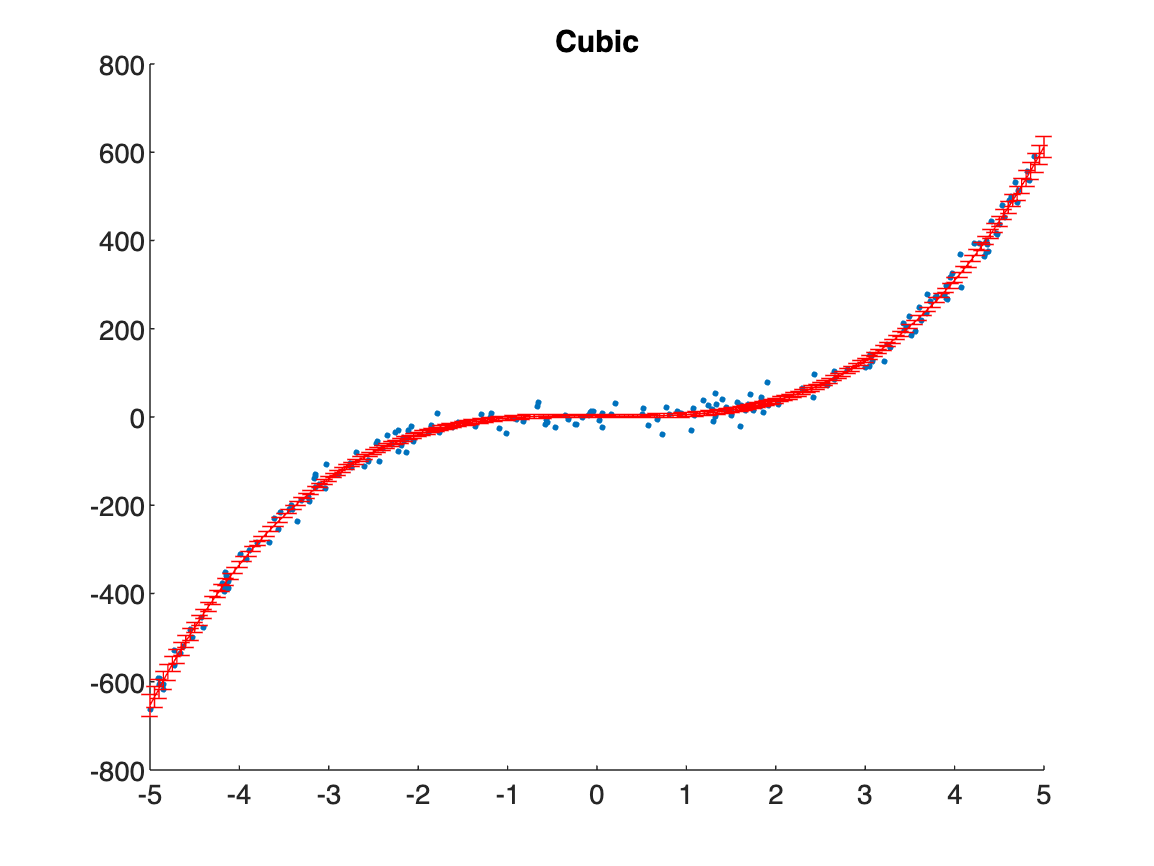


figure(2);
scatter(x,t,5,'filled'); hold on;
plot(xtest,that_cubic, '-y'); 
errorbar(xtest, that_cubic, that_cubic_var, '-r'); 
title("Cubic");hold off;

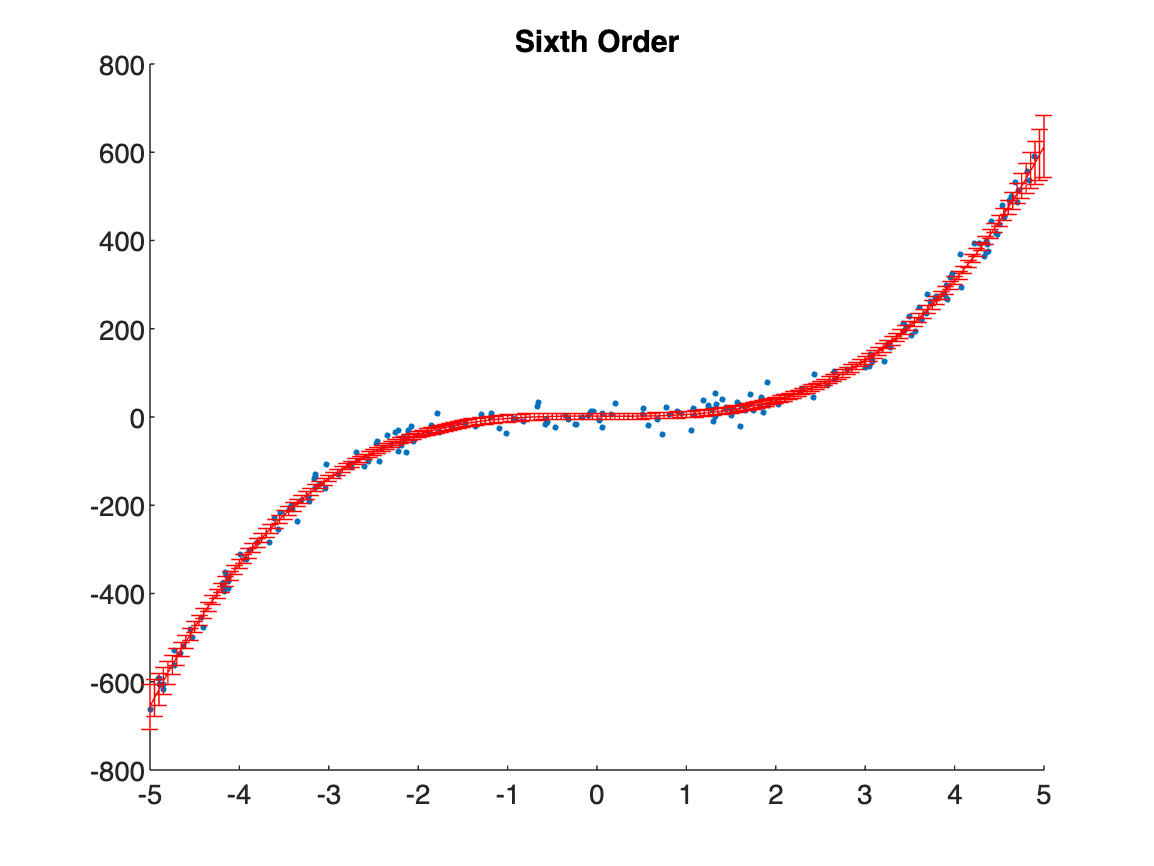

% plot(xtest, that_sixth, '-g');
figure(3);
scatter(x,t,5,'filled'); hold on;
plot(xtest,that_sixth, '-y'); 
errorbar(xtest, that_sixth, that_sixth_var, '-r');
title("Sixth Order");hold off;